# Recepcion trama robot

## Objeto serial

baudRate=115200;
serialportlist

ans = 1×2 string array
    "/dev/ttyS0"    "/dev/ttyUSB0"


%UsarACM0 para recibir datos de la Launchpad
%ACM1 no envía datos. Se usa para debug propio.
%s=serialport("/dev/ttyACM0",baudRate,'Timeout',30)
s=serialport("/dev/ttyUSB0",baudRate,'Timeout',30)

s =   Serialport with properties:

                 Port: "/dev/ttyUSB0"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions


## Algunas configuraciones

dataMatrix=[];
configureTerminator(s,"CR/LF")
%s.Terminator
flush(s)

## Lectura

%while 1
dataRecieved=read(s,254,'uint8');
dataMatrix=[dataMatrix;dataRecieved];

%end

## Decodificación

## Sólo para cargar archivos dummy

load RFData.mat

## Inicialización

%Número de muestras a recordar
ind=70;
[READINGS] = initTables(ind);

%D=size(dataMatrix);
%ind=D(1);

% 
% %Tabla de cabecera
% Cabecera=array2table(zeros(ind,3),'VariableNames',["Header" "Robot_ID" "DBG_MSG"]);
% Cabecera.Header=string(Cabecera.Header);
% 
% %Tabla de motores
% MOTORS=array2table(zeros(ind,4),'VariableNames',["Imot" "Isys" "MotorStatus" "IsysStatus"]);
% 
% %Tabla de bobina
% BOBINA=array2table(zeros(ind,15),'VariableNames',["ClusterSize" "BandsDetected" "PSD_B1" "PSD_B2" "PSD_B3" "PSD_B4" "PSD_B5" ...
%     "PSD_B6" "PSD_B7" "PSD_B8" "PSD_B9" "PSD_B10" "PSD_B11" "PSD_Base" "BandsEmitted"]);
% 
% %Tabla navigation
% NAVIGATION=array2table(zeros(ind,9),'VariableNames', ...
%     ["CurrentState" "NextState" "nav_Cycs" "ACS" "LCS" "ClusterChanged" ...
%      "BetterClusterFound" "MovStatus" "EscStrategy"]);
% 
% %Tabla RSSI primer sondeo
% RSSI_1Son=array2table(zeros(12*ind,7),'VariableNames',["CH1" "CH2" "CH3" "CH4" "CH5" "Sondeo" "Step"]);
% 
% %Tabla RSSI segundo sondeo
% RSSI_2Son=array2table(zeros(12*ind,7),'VariableNames',["CH1" "CH2" "CH3" "CH4" "CH5" "Sondeo" "Step"]);
% 
% %Tabla THRESHOLD segundo sondeo
% THRESHOLD=array2table(zeros(ind,5),'VariableNames',["Max1" "Max2" "Max3" "Thld" "StepSelect"]);
% 
% %Statistics
% dummyVariable=zeros(ind,5);
% STAT_RSSI=table(dummyVariable,dummyVariable,dummyVariable,dummyVariable,dummyVariable,dummyVariable, ...
%     'VariableNames',["Son1_median" "Son1_1Q" "Son1_3Q" "Son2_median" "Son2_1Q" "Son2_3Q"]);


## Llenado de tablas


for i=1:D(1)
    
    %Cabecera
    Cabecera{i,"Header"}=string(char(uint8(dataMatrix(1,1:3))));       
    Cabecera{i,"Robot_ID"}=uint8(dataMatrix(i,4));    
    Cabecera{i,"DBG_MSG"}=typecast(uint8(dataMatrix(i,5:6)),'uint16');
        
    %Motores
    for j=1:4 
        if j<=2
        MOTORS{i,j}=typecast(uint8(dataMatrix(i,(9:12)+4.*(j-1))),'single');     
        else
        MOTORS{i,j}=typecast(uint8(dataMatrix(i,(17:18)+2.*(j-3))),'uint16');    
        end
    end
    
    %Tabla de bobina    
    BOBINA{i,"ClusterSize"}=typecast(uint8(dataMatrix(i,21:22)),'uint16');
    BOBINA{i,"BandsDetected"}=typecast(uint8(dataMatrix(i,23:24)),'uint16');
    for j=3:14
        BOBINA{i,j}=typecast(uint8(dataMatrix(i,(25:28)+4.*(j-3))),'single');     
    end
    BOBINA{i,"BandsEmitted"}=typecast(uint8(dataMatrix(i,73:74)),'uint16');
    
    %Navigaion
    NAVIGATION{i,"CurrentState"}=typecast(uint8(dataMatrix(i,77:80)),'int32');
    NAVIGATION{i,"NextState"}=typecast(uint8(dataMatrix(i,81:84)),'int32');
    NAVIGATION{i,"nav_Cycs"}=typecast(uint8(dataMatrix(i,85:86)),'uint16');
    NAVIGATION{i,"ACS"}=uint8(dataMatrix(i,87));
    NAVIGATION{i,"LCS"}=uint8(dataMatrix(i,88));
    NAVIGATION{i,"ClusterChanged"}=logical(dataMatrix(i,89));
    NAVIGATION{i,"BetterClusterFound"}=logical(dataMatrix(i,90));
    NAVIGATION{i,"MovStatus"}=uint8(dataMatrix(i,91));
    NAVIGATION{i,"ACS"}=uint8(dataMatrix(i,91));
    
    %RSSI primer sondeo
    RSSI_1Son{(1:12)+(i-1)*12,1:end-2}=reshape(uint8(dataMatrix(i,93:152)),5,12)';
    RSSI_1Son{(1:12)+(i-1)*12,"Sondeo"}=repmat(i,12,1);
    RSSI_1Son{(1:12)+(i-1)*12,"Step"}=(1:12)';
    
    %RSSI segundo sondeo
    RSSI_2Son{(1:12)+(i-1)*12,1:end-2}=reshape(uint8(dataMatrix(i,153:212)),5,12)';
    RSSI_2Son{(1:12)+(i-1)*12,"Sondeo"}=repmat(i,12,1);
    RSSI_2Son{(1:12)+(i-1)*12,"Step"}=(1:12)';
    
    %THRESHOLD
    THRESHOLD{i,"Max1"}=typecast(uint8(dataMatrix(i,213:216)),'single'); 
    THRESHOLD{i,"Max2"}=typecast(uint8(dataMatrix(i,217:220)),'single'); 
    THRESHOLD{i,"Max3"}=typecast(uint8(dataMatrix(i,221:224)),'single'); 
    THRESHOLD{i,"Thld"}=typecast(uint8(dataMatrix(i,225:228)),'single'); 
    THRESHOLD{i,"StepSelect"}=uint8(dataMatrix(i,229)); 
end

Unrecognized function or variable 'D'.

## Estadísticas y métricas

%Estadistica de RSSI
for k=1:D(1)
%Estadistica de RSSI primer sondeo
RSSI_1Son_statistics_data=RSSI_1Son{(1:12)+12*(k-1),["CH1" "CH2" "CH3" "CH4" "CH5"]};
RSSI_1Son_statistics_median(k,:)=median(RSSI_1Son_statistics_data);    
RSSI_1Son_statistics_3Q(k,:)=quantile(RSSI_1Son_statistics_data,0.75);
RSSI_1Son_statistics_1Q(k,:)=quantile(RSSI_1Son_statistics_data,0.25);

%Estadistica de RSSI segundo sondeo
RSSI_2Son_statistics_data=RSSI_2Son{(1:12)+12*(k-1),["CH1" "CH2" "CH3" "CH4" "CH5"]};
RSSI_2Son_statistics_median(k,:)=median(RSSI_2Son_statistics_data);    
RSSI_2Son_statistics_3Q(k,:)=quantile(RSSI_2Son_statistics_data,0.75);
RSSI_2Son_statistics_1Q(k,:)=quantile(RSSI_2Son_statistics_data,0.25);
end




## Sondeo 1 y 2

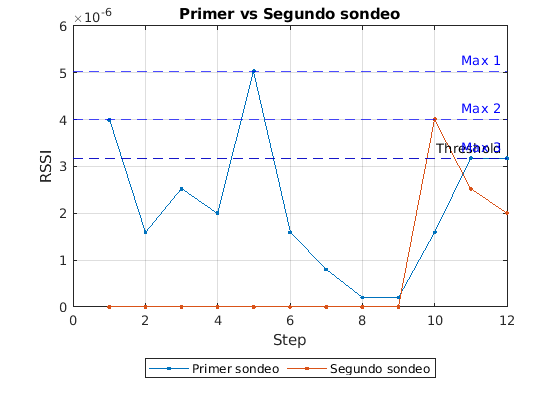

%idx=RSSI_1Son.Sondeo==D(1);
numSondeo=3;
idx=RSSI_1Son.Sondeo==numSondeo;
Son1_lin=sum(10.^(-RSSI_1Son{idx,1:5}./10),2);
Son2_lin=sum(10.^(-RSSI_2Son{idx,1:5}./10),2);
%Cambiar 1 por cero
Son1_lin(Son1_lin>=1)=0;
Son2_lin(Son2_lin>=1)=0;

thresh_ord=sort(Son1_lin,'descend');
thresh=(thresh_ord(2)+thresh_ord(3))./2;

figure
% tiledlayout(2,1)
% nexttile
plot(Son1_lin,'.-')
hold on
plot(flipud(Son2_lin),'.-')
yline(THRESHOLD.Thld(numSondeo),'k--','Threshold')
yline(THRESHOLD.Max1(numSondeo),'b--','Max 1')
yline(THRESHOLD.Max2(numSondeo),'b--','Max 2')
yline(THRESHOLD.Max3(numSondeo),'b--','Max 3')
hold off
ylabel("RSSI")
legend("Primer sondeo","Segundo sondeo",'Location','southoutside','Orientation',"horizontal")
xlabel("Step")
title("Primer vs Segundo sondeo")
grid on

## RSSI primer sondeo

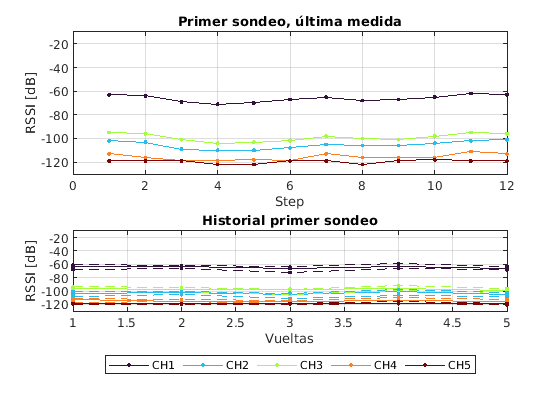

%% Ploteo
cmap=turbo(5);
id_state=NAVIGATION.CurrentState==1;

%Lectura actual
figure
subplot(2,1,1)
plot(RSSI_1Son.Step(end-11:end),-RSSI_1Son{end-11:end,1:5},'.-')
ylabel("RSSI [dB]")
xlabel("Step")
ylim([-130 -10])
title("Primer sondeo, última medida")
grid on
ax=gca;
ax.ColorOrder=cmap;

%Lecturas pasadas
subplot(2,1,2)
%figure
plot(-RSSI_1Son_statistics_median(id_state,:),'.-')
hold on
plot(-RSSI_1Son_statistics_3Q(id_state,:),'.--')
plot(-RSSI_1Son_statistics_1Q(id_state,:),'.--')
hold off
ylabel("RSSI [dB]")
xlabel("Vueltas")
title("Historial primer sondeo")
ylim([-130 -10])
grid on
ax=gca;
ax.ColorOrder=cmap;
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")


%end

## RSSI primer sondeo lineal

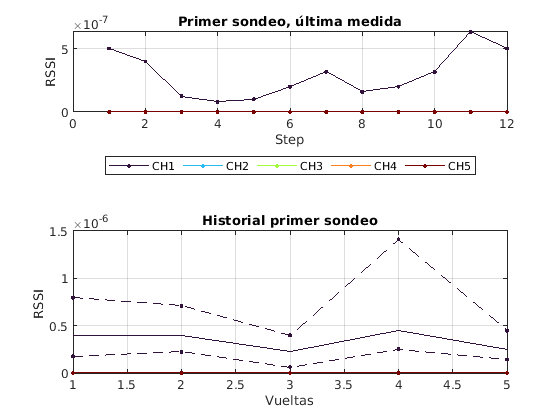

%Lectura actual
figure
subplot(2,1,1)   
plot(RSSI_1Son.Step(end-11:end),10.^(-RSSI_1Son{end-11:end,1:5}./10),'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI")
xlabel("Step")
title("Primer sondeo, última medida")
grid on
ax=gca;
ax.ColorOrder=cmap;


%Lecturas pasadas
%figure
subplot(2,1,2)
plot(10.^(-RSSI_1Son_statistics_median(id_state,:)./10))
hold on
plot(10.^(-RSSI_1Son_statistics_3Q(id_state,:)./10),'.--')
plot(10.^(-RSSI_1Son_statistics_1Q(id_state,:)./10),'.--')
hold off
ylabel("RSSI ")
xlabel("Vueltas")
title("Historial primer sondeo")
grid on
ax=gca;
ax.ColorOrder=cmap;

%end

## RSSI primer sondeo log

%readingNo=max(RSSI.Reading);

readingNo=2;
index=RSSI_1Son.Sondeo==readingNo;

figure
subplot(2,1,1)
title("RSSI por canal")
plot(RSSI_1Son.Step(index),-RSSI_1Son{index,1:5},'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Step")
ylim([-130 -10])
title("RSSI Lectura "+readingNo)
grid on
ax=gca;
ax.ColorOrder=cmap;


## RSSI primer sondeo lin

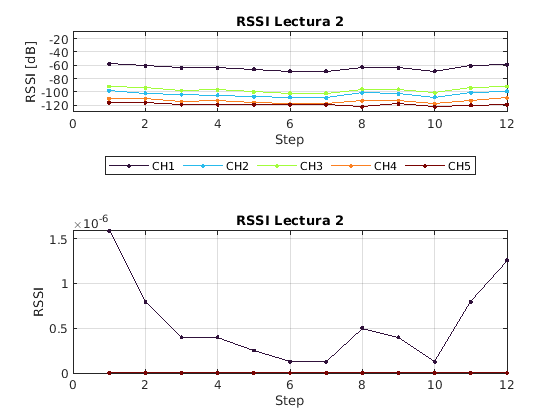

subplot(2,1,2)
plot(RSSI_1Son.Step(index),10.^((-RSSI_1Son{index,1:5})./10),'.-')
%legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI")
xlabel("Step")
%ylim([-130 -10])
title("RSSI Lectura "+readingNo)
grid on
ax=gca;
ax.ColorOrder=cmap;

## RSSI segundo sondeo

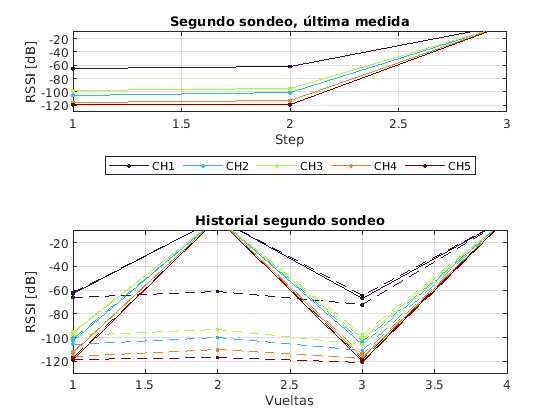

%% Ploteo
cmap=turbo(5);
id_state=NAVIGATION.CurrentState==1;

%Lectura actual
figure
subplot(2,1,1)
plot(RSSI_2Son.Step(end-11:end),-RSSI_2Son{end-11:end,1:5},'.-')
%colormap turbo
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Step")
ylim([-130 -10])
title("Segundo sondeo, última medida")
grid on
ax=gca;
ax.ColorOrder=cmap;

%Lecturas pasadas
subplot(2,1,2)
%figure
plot(-RSSI_2Son_statistics_median(id_state,:),'.-')
hold on
plot(-RSSI_2Son_statistics_3Q(id_state,:),'.--')
plot(-RSSI_2Son_statistics_1Q(id_state,:),'.--')
hold off
ylabel("RSSI [dB]")
xlabel("Vueltas")
title("Historial segundo sondeo")
ylim([-130 -10])
grid on
ax=gca;
ax.ColorOrder=cmap;

%end

## RSSI Lineal

%Lectura actual
figure
%subplot(2,1,1)   
ax = axes;
ax.ColorOrder = cmap;
ax.NextPlot = 'add';
plot(RSSI_2Son.Step(end-11:end),10.^(-RSSI_2Son{end-11:end,1:5}./10),'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI")
xlabel("Step")
%ylim([-130 -10])
title("Segundo sondeo, última medida")
grid on

%Lecturas pasadas
figure
%subplot(2,1,2)
ax = axes;
ax.ColorOrder = cmap;
ax.NextPlot = 'add';
plot(10.^(-RSSI_2Son_statistics_median(id_state,:)./10))
hold on
plot(10.^(-RSSI_2Son_statistics_3Q(id_state,:)./10),'.--')
plot(10.^(-RSSI_2Son_statistics_1Q(id_state,:)./10),'.--')
hold off
ylabel("RSSI ")
xlabel("Vueltas")
title("Historial segundo sondeo")
grid on
%ylim([-130 -10])
%end

## RSSI primer sondeo log

%readingNo=max(RSSI.Reading);

readingNo=2;
index=RSSI_2Son.Sondeo==readingNo;

figure
title("RSSI por canal")
plot(RSSI_2Son.Step(index),-RSSI_2Son{index,1:5},'.-')
legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
ylabel("RSSI [dB]")
xlabel("Step")
ylim([-130 -10])
title("RSSI Lectura "+readingNo)
grid on



## RSSI primer segundo lin

%readingNo=2;
%index=RSSI_1Son.Sondeo==readingNo;
figure
    plot(RSSI_2Son.Step(index),10.^((-RSSI_2Son{index,1:5})./10),'.-')
    legend(["CH1" "CH2" "CH3" "CH4" "CH5"],'Location',"southoutside",'Orientation',"horizontal")
    ylabel("RSSI")
    xlabel("Step")
    %ylim([-130 -10])
    title("RSSI Lectura "+readingNo)
    grid on


## Graficado

% %tiledlayout('flow')
% figure
% %nexttile
% plot(MOTORS{:,["Imot" "Isys"]},'o-')
% ylabel("[mA]")
% title("Consumo de corriente")
% legend(["Motores" "Sistema"])
% 


## Potencia en bobinas


% figure
% %plot(BOBINA{:,3:14},'o-')
% bar(BOBINA{:,3:15})
% ylabel("PSD Total [V^2/Hz]")
% title("Potencia espectral en bobinas")
% legend(["B"+(1:11) "Umbral"],'Location',"eastoutside")


## Cluster size

% figure
% bar(BOBINA{:,["ClusterSize" "BandsDetected" "BandsEmitted"]})
% legend(["ClusterSize" "BandsDetected" "BandsEmitted"])
% %Bands emited y detectadas
% %dec2bin(typecast(uint8(dataMatrix(i,71:72)),'uint16'),16)
% %el resultado se lee de derecha a izquierda
% %Cada bit representa una banda

## RSSI por lectura

% readingNo=max(RSSI.Reading);
% %index=RSSI.Reading==readingNo;
% figure
% %gscatter(RSSI.Angle,RSSI{:,1:5},RSSI.Angle)
% title("RSSI contra lectura")
% plot(RSSI.Reading,-RSSI{:,1:5},'-o')
% legend(["CH1" "CH2" "CH3" "CH4" "CH5"])
% ylabel("RSSI [dB]")
% xlabel("Angulo")
% ylim([-130 -10])
% title("RSSI Lectura "+readingNo)
